clear all

fn = "2025-01-27-11-03-47.bag";

bag = rosbag(fn);

t_start = 1 ; % in ms
t_end = 30*1000 + t_start;  % in ms

% bag = rosbag("bags/2025-01-16-16-08-08.bag");


% setPointTopic = select(bag,'Topic','/setpoint');
botstatetopic = select(bag,'Topic','/state');

botstateTwisttopic = select(bag,'Topic','/tb_vel');
% errorTopic = select(bag,'Topic','/error');
cmdTopic = select(bag,'Topic','/cmd');



% setPointmsgs = readMessages(setPointTopic,'DataFormat','struct');
% [sp, t_sp] = pose2mat(setPointmsgs);

msgPose = readMessages(botstatetopic,'DataFormat','struct');
[pose_ros, t_pose]=pose2mat(msgPose);


% P_Position_msgs = readMessages(botstatePtopic,'DataFormat','struct');
% [p, t_p]=pose2mat(P_Position_msgs);


tb_vel_msgs = readMessages(botstateTwisttopic,'DataFormat','struct');
[tb_t, t_t]=twist2mat(tb_vel_msgs);

cmd_msgs = readMessages(cmdTopic,'DataFormat','struct');
[cmd, t_c]=twist2mat(cmd_msgs);


% start_sp = find(t_sp>t_start,1); 
% start_p = find(t_p>t_start,1);
% start_e = find(t_e>t_start,1); 
start_p = find(t_pose>t_start,1); 
start_c = find(t_c>t_start,1); 
% cutoff_sp = find(t_sp>t_end,1); 
% cutoff_p = find(t_p>t_end,1); 
% cutoff_e = find(t_e>t_end,1); 
cutoff_p = find(t_pose>t_end,1); 
cutoff_c = find(t_c>t_end,1); 

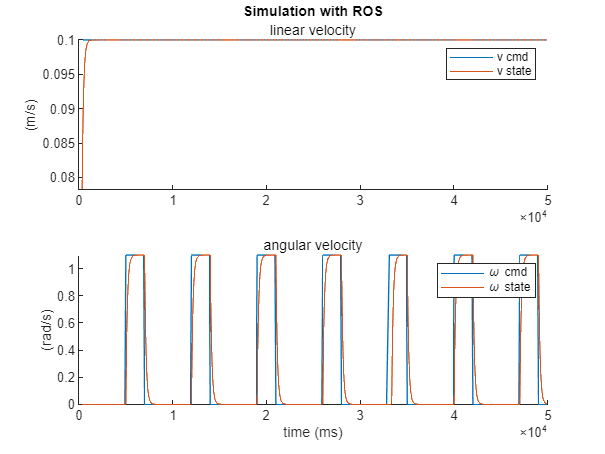

figure
subplot(2,1,1);
    hold on
    plot(t_c,cmd(:,1))
    plot(t_t,tb_t(:,1))
    hold off
    legend("v cmd","v state")
subtitle("linear velocity")
title("Simulation with ROS")
ylabel("(m/s)")
subplot(2,1,2);
    hold on
    plot(t_c,cmd(:,2))
    plot(t_t,tb_t(:,2))
    hold off
    legend("\omega cmd","\omega state")
subtitle("angular velocity")
% legend('X axis','Y axis','Location','northeast')
ylabel("(rad/s)")
xlabel("time (ms)")

% figure
% subplot(2,1,1);
% plot(t_c(start_c:cutoff_c)-t_start,cmd(start_c:cutoff_c,1))
% title("Simulation with ROS")
% legend('Vel','Location','northeast')
% ylabel("vel (m/s)")
% subtitle("CMD")
% subplot(2,1,2); 
% plot(t_c(start_c:cutoff_c)-t_start,cmd(start_c:cutoff_c,2))
% legend("Rotation",'Location','northeast')
% ylabel("omega (rad/s)")
% xlabel("time (ms)")



figure
hold on
    % plot(sp(start_sp:cutoff_sp,1),sp(start_sp:cutoff_sp,2))
    plot(pose_ros(start_p:cutoff_p,1),pose_ros(start_p:cutoff_p,2))
hold off
title("Simulation with ROS")
subtitle("Trajectory comparison")
legend("ROS simulation","output")

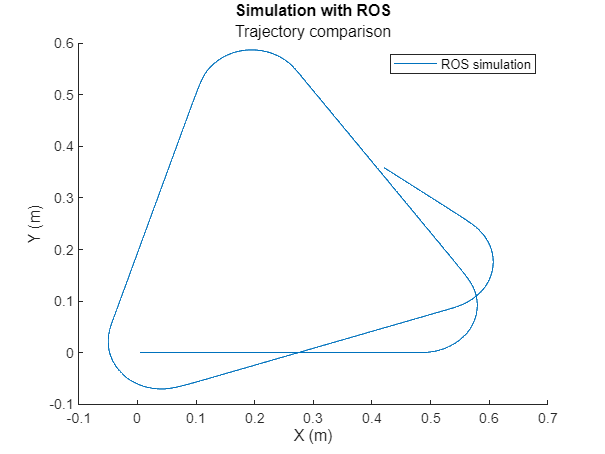

% ylim([-3 4])
ylabel("Y (m)")
xlabel("X (m)")


function [matrix,t] = pose2mat(msgs)
    matrix = zeros(numel(msgs),2);
    t = zeros(numel(msgs),1);
    for i=1:numel(msgs)
        matrix(i,1) = msgs{i,1}.Pose.Position.X;
        matrix(i,2) = msgs{i,1}.Pose.Position.Y;
        t(i,1) = 10^3* msgs{i,1}.Header.Stamp.Sec + 10^-6 * msgs{i,1}.Header.Stamp.Nsec;
    end

end

function [matrix,t] = vec3tomat(msgs)
    matrix = zeros(numel(msgs),2); % x y magnitude in column
    t = zeros(numel(msgs),1); % time in milliseconds
    for i=1:numel(msgs)
        matrix(i,1) = msgs{i,1}.Vector.X;
        matrix(i,2) = msgs{i,1}.Vector.Y;
        % matrix(i,3) = sqrt(msgs{i,1}.Vector.X^2+msgs{i,1}.Vector.Y^2);
        t(i,1) = 10^3* msgs{i,1}.Header.Stamp.Sec + 10^-6 * msgs{i,1}.Header.Stamp.Nsec;
    end

end

function [matrix,t] = twist2mat(msgs)
    matrix = zeros(numel(msgs),2); % x y magnitude in column
    t = zeros(numel(msgs),1); % time in milliseconds
    for i=1:numel(msgs)
        matrix(i,1) = msgs{i,1}.Twist.Linear.X;
        matrix(i,2) = msgs{i,1}.Twist.Angular.Z;
        % matrix(i,3) = sqrt(msgs{i,1}.Vector.X^2+msgs{i,1}.Vector.Y^2);
        t(i,1) = 10^3* msgs{i,1}.Header.Stamp.Sec + 10^-6 * msgs{i,1}.Header.Stamp.Nsec;
    end

end